# Bioimpedance measurements

Copyright (C) 2022 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter9/Bioimpedance'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook we will show a way how to implement a model for estimating breathing rate using bioimpedance measurements. The impedance circuit is shown below.

We will describe the figure below. Fixed impedance of the thorax is  modeled to be 500 Ω. The impedance due to breathing changes as a sine  wave at the amplitude of 5 Ω. We selected 5 Ω (and not 1 as explained  before) so that we can present the changes due to breathing on the  modulated signal.  The breathing is simulated as a sine wave at the  frequency of 12 breaths per minute. These two impedances are connected  in series and represent the impedance of the thorax. Four electrodes are connected to the chest and they are modeled as wet electrodes with the  same parameters as the parameters of wet electrodes introduced in  Chapter 3. Two drive electrodes are labeled ElectrodeSkinModel1 and  ElectrodeSkinModel2. These drive is coming from the voltage source that  is set at the frequency of 32 kHz and the amplitude 1 V peak to peak. It connects to the resistors R1 and R2 (40 k Ω) and capacitors C1 and C2  (0.1 nF). The purpose of the resistor is to limit the current through  the body – in this case it is maximum 2V/12.5= 25 µA which is the  current that is considered safe at 32 kHz. Actually, maximum allowable  peak-to-peak current below 1 kHz is 10 µApp where pp means peak to peak. At the frequencies higher than 1 kHz, the peak to peak current is  determined as  . Capacitors C1 and C2 block any direct current current from flowing into the chest body from the drive side. Capacitors C3 and C4 serve the same purpose on the measurement side. The signal is then amplified, passed  through the high pass with 10 kHz cut-off frequency as well as the low  pass filter to prevent aliasing. A/D conversion is performed at 1 MHz  using 16 bit A/D converter. The demodulation in this case is done in  digital domain. This circuit is described in the data sheet for the  Analog Devices chip ADAS1000. Demodulation is performed in digital domain. 

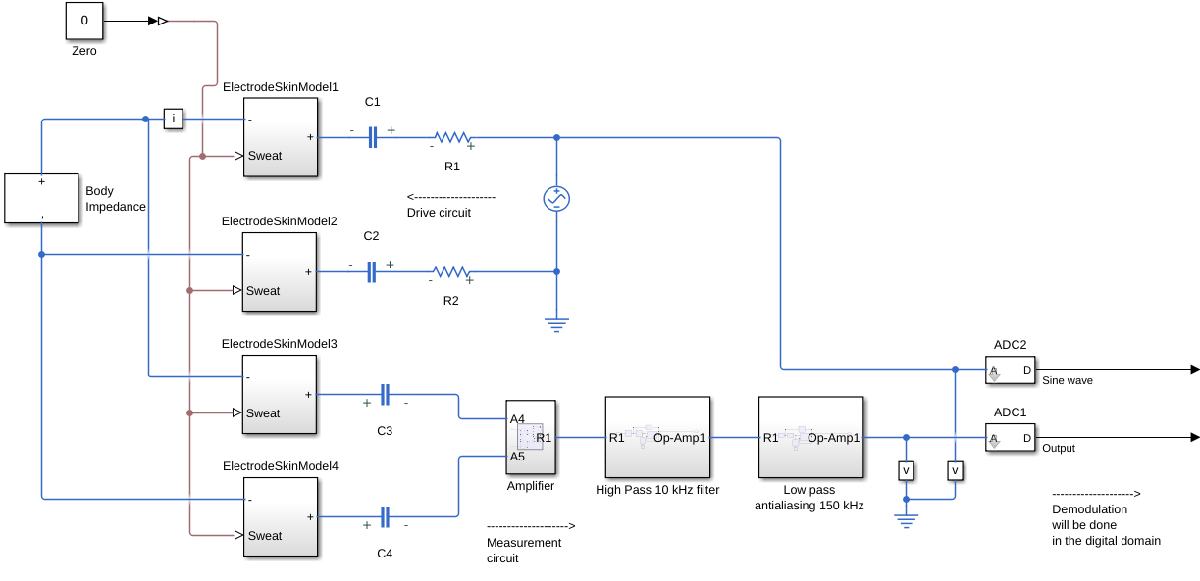

## Generating the respiration signal

In this section we generate respiration signal as impedance change. Please note that the fixed impedance of the thorax is assumed to be 500 Ohm. We are adding dynamic compument to it. Therefore, signal delta_R is presented in Ohms.

fs=100000;
N=10*fs;
T=1/fs;
t = (0:N-1)*T;  
br_freq=0.2; 
delta_R_ampl=5;
delta_R=(delta_R_ampl+delta_R_ampl*sin(2*pi*t*br_freq))';%+(delta_R_ampl/5)*randn(length(t),1);
plot(t,delta_R);
    title('Changes in impedance')
    xlabel('Time (s)')
    ylabel('Amplitude (Ohm)')
resp(:,1)=t;
resp(:,2)=delta_R;



## Simulating the system in Simscape

PLEASE NOTE THAT THE SIMULATION IS VERY SLOW BECAUSE OF HIGH SAMPLING RATE. It might take several hours.

model_name = 'Bioimpedance_digital';
open_system(model_name);
s=sim(model_name);

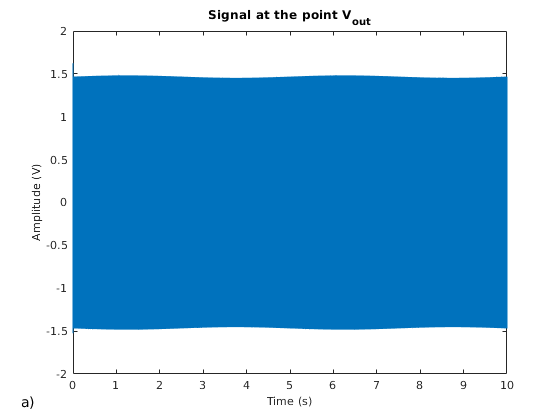

% Plotting the output
figure
plot(s.simout.Time(1000:end), s.simout1.Data(1000:end))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Amplitude (V)', 'FontSize', 10)
title('Signal at the point V_{out}')
annonation_save('a)',"Fig9.13a.jpg", SAVE_FLAG);

% Resampling the signal from Simscape
fs1=512000;
a=resample(s.simout1.Data,s.simout1.Time,fs1);
sin_res=resample(s.simout.Data,s.simout.Time,fs1);
cos_res=sin_res(5:end);  % proper pi/2 delay would need to be implemented
t1=1/fs1:1/fs1:length(cos_res)/fs1;

## Demodulation

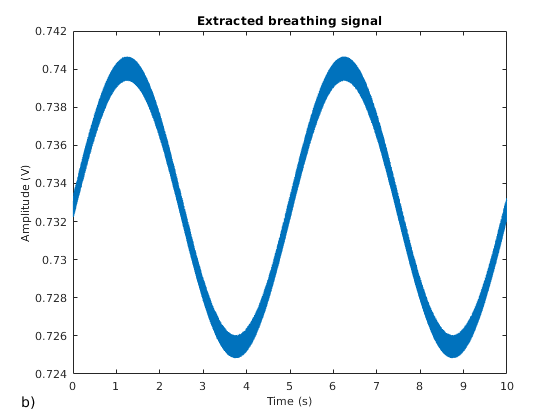

% Obtaining I and Q components
Vi=a(1:length(cos_res)).*sin_res(1:length(cos_res));
Vq=a(1:length(cos_res)).*cos_res;

%Filtering the components. Cutoff frequency is 7 kHz since the modulation
%signal is 32 kHz.
Vi_f=lowpass(Vi, 7000, fs1);
Vq_f=lowpass(Vq, 7000, fs1);

% Computing the amplitude, phase and the output signal
V=sqrt(Vi_f.^2+Vq_f.^2);
theta=atan(Vq_f./Vi_f);

% Plotting - without the artifacts in the beginning and in the end

plot(t1(5000:end-5000), V(5000:end-5000))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Amplitude (V)', 'FontSize', 10)
title('Extracted breathing signal')
annonation_save('b)',"Fig9.13b.jpg", SAVE_FLAG);

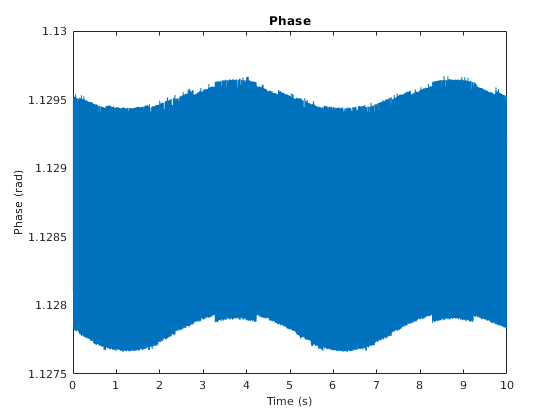

figure
plot(t1(5000:end-5000), theta(5000:end-5000))
xlabel('Time (s)', 'FontSize', 10)
ylabel('Phase (rad)', 'FontSize', 10)
title('Phase')

%save('s.mat','s')
% Breathing rate estimation (requires at leatr 2 breathing periods)
br_rate_est(smooth(V(5000:end-5000)),fs1)

ans = 12.0400

So, the estimated breathing rate is very close to the breathing rate that we started with which was 0.2 Hz or 12 breaths per minute.

***Exercizes:***

- Modify the simulation by turning the indicator for sweating to 1. This will allow for much better contact between the electrodes and the skin. Observe the amplitude of the signal at the output.

- Reduce the ampliture of the impedance change from 5 to 1 Ohm and then to 0.2 Ohm. Observe the signal at the output.

- Remove electrodes 3 and 4 (blocks ElectrodeSkinModel3 and ElectrodeSkinModel4) from the simulator and connect capacitors C3 and C4 directly to the first 2 electrodes (C3 to the + input of ElectrodeSkinModel1 and C4 to the + input of the ElectrodeSkinModel2). Compare the putput of the two electrode system with the output of the four electrode system. Why is there such a big difference?

- Add noise source to the signal  delta_R by uncommenting the noise term in the line when delta_R is formed. How is the standard deviation of the noise affect the results.

- Modify the circuit to implement demodulation in hardware instead of processing it in the digital domain. You would need to remove the high pass filter and to modify cut-off frequency of the anialiasing filter to be in the order of 100 Hz. Use mixer (multiplier) blocks from Simulink in this case. You would need to convert the signal from Simscape to Simulink in order to multiply it. Lowpass filter after the mixer can be implemented in Simulink or in Simscape. 